# Data Driven Simulation Nuclear Norm

## First attempt future prediction with 3 states

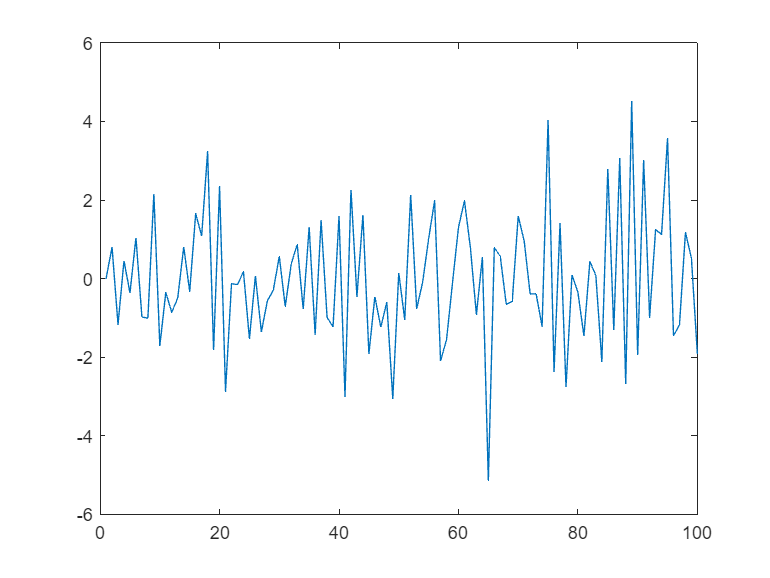

addpath('./tensorlab');
addpath('./cvx');

% Define system dimensions
statenum = 3;
outputnum = 1;
inputnum = 1;
maxTime = 100; % Total time for simulation of historical data
predTime = 1; % Part of the time that is the future

% Create a discrete-time random state space model
sys = drss(statenum, outputnum, inputnum);

% Generate a persistently exciting input for historical data
% For example, a random signal
u_trajectory = randn(inputnum, maxTime)';

% New input for prediction
% newInputTime = predTime; % Length of new input
% uf = randn(inputnum, newInputTime); % New input sequence
% uf = zeros(inputnum,1); %zero input

% Simulate the system to generate historical outputs
% Assuming zero initial state for simplicity
x0 = zeros(statenum, 1); % Initial state
[data, t, x] = lsim(sys, u_trajectory, linspace(0, maxTime-1, maxTime), x0);
plot(data)

% scaling the past data by some gamma

minValue = min(min(data(:)),min(u_trajectory(:)));
maxValue = max(max(data(:)),max(u_trajectory(:)));

absoluteLargestValue = max(abs(minValue),abs(maxValue));

gamma = 10^ceil(log10(absoluteLargestValue))

gamma =     10



% normalize everything except future points
dataNorm = data/gamma

dataNorm =                    0
   0.080113935903982
  -0.117141608605697
   0.045283015528553
  -0.036789697621159
   0.104139167613507
  -0.097860664807252
  -0.100899990149966
   0.216175111842058
  -0.171213285424926


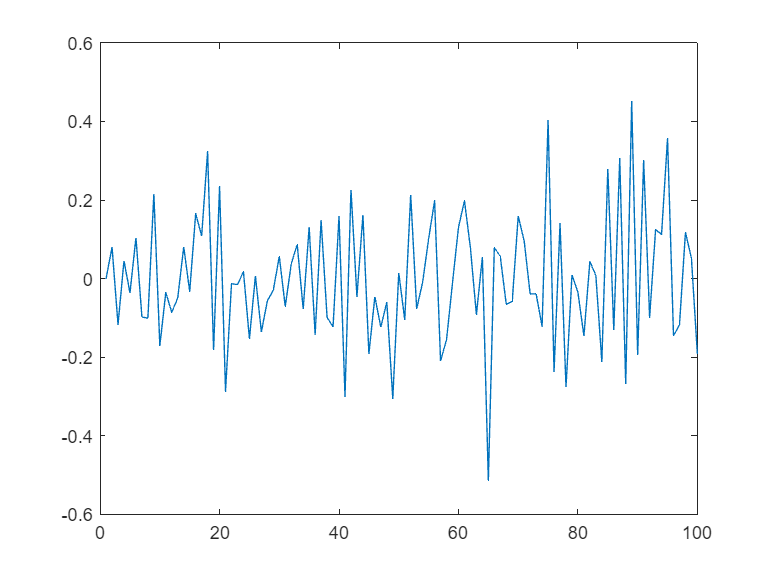

u_trajectoryNorm = u_trajectory/gamma;

plot(dataNorm)


dataLength = length(data);

lag = 11;

% Create the full Hankel matrix without missing values initially
HankelMatrix = mosaicHankel(u_trajectoryNorm, dataNorm, lag);

OriginalHankel = HankelMatrix;

% Define the number of points we want to predict (missing at the end)
numPredict = 1;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns

% For the last column
mask(end-numPredict+1:end, end) = false;

%{
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end
%}

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Proceed with matrix completion using the nuclear norm minimization (using CVX)
cvx_begin quiet %sdp for logs
    variable CompleteHankel(size(HankelMatrix))
    minimize(norm_nuc(CompleteHankel))
    subject to
        % Ensure the known entries remain the same
        CompleteHankel(mask) == HankelMatrix(mask);
cvx_end
% Check the completion status
disp(cvx_status);

Solved



predictedValues = CompleteHankel(end, end-numPredict+1:end)*gamma;

disp('Predicted value:');

Predicted value:


format long;
disp(predictedValues);

  -1.931176467401391



disp('Actual value:');

Actual value:


disp(transpose(data(end-numPredict+1:end)))

  -1.931176481041162



%rmse(predictedValues,transpose(data(end-numPredict+1:end)))
%currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues)

currentError = norm(predictedValues,2)/norm(transpose(data(end-numPredict+1:end)))

currentError =    0.999999992937067


## Multiple iterations with 10 states

% Number of iterations
iterations = 20;

% Initialize arrays to store results
predictedValues = zeros(iterations, 1);
actualValues = zeros(iterations, 1);
errors = zeros(iterations, 1);

for iter = 1:iterations
   % Define system dimensions
    statenum = 10;
    outputnum = 1;
    inputnum = 1;
    maxTime = 100; % Total time for simulation of historical data
    predTime = 1; % Part of the time that is the future
    
    % Create a discrete-time random state space model
    sys = drss(statenum, outputnum, inputnum);
    
    % Generate a persistently exciting input for historical data
    % For example, a random signal
    u_trajectory = randn(inputnum, maxTime)';
    
    % New input for prediction
    % newInputTime = predTime; % Length of new input
    % uf = randn(inputnum, newInputTime); % New input sequence
    % uf = zeros(inputnum,1); %zero input
    
    % Simulate the system to generate historical outputs
    % Assuming zero initial state for simplicity
    x0 = zeros(statenum, 1); % Initial state
    [data, t, x] = lsim(sys, u_trajectory, linspace(0, maxTime-1, maxTime), x0);
    % scaling the past data by some gamma
    
    minValue = min(min(data(:)),min(u_trajectory(:)));
    maxValue = max(max(data(:)),max(u_trajectory(:)));
    
    absoluteLargestValue = max(abs(minValue),abs(maxValue));
    
    gamma = 10^ceil(log10(absoluteLargestValue));
    
    % normalize everything except future points
    dataNorm = data/gamma;
    u_trajectoryNorm = u_trajectory/gamma;
    
    
    dataLength = length(data);
    
    lag = statenum+1;
    
    % Create the full Hankel matrix without missing values initially
    HankelMatrix = mosaicHankel(u_trajectoryNorm, dataNorm, lag);
    
    % Define the number of points we want to predict (missing at the end)
    numPredict = 1;
    
    % Create a logical mask for the Hankel matrix with all ones (no missing data)
    mask = true(size(HankelMatrix));
    
    % Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
    % These points appea5r in the last 'numPredict' rows of the last columns
    
    % For the last column
    mask(end-numPredict+1:end, end) = false;
    
    %{
    for i = 1:numPredict
        mask(end-i+1, end-numPredict+i:end) = false;
    end
    %}
    
    % Now, apply the mask to set the last 'numPredict' points as NaN (missing)
    HankelMatrix(~mask) = NaN;
    
    % Proceed with matrix completion using the nuclear norm minimization (using CVX)
    cvx_begin quiet %sdp for logs
        variable CompleteHankel(size(HankelMatrix))
        minimize(norm_nuc(CompleteHankel))
        subject to
            % Ensure the known entries remain the same
            CompleteHankel(mask) == HankelMatrix(mask);
    cvx_end


    predicted = CompleteHankel(end, end-numPredict+1:end)*gamma;

    %rmse(predictedValues,transpose(data(end-numPredict+1:end)))
    %currentError = abs(predictedValues-transpose(data(end-numPredict+1:end)))/abs(predictedValues)
    
    currentError = norm(predicted,2)/norm(transpose(data(end-numPredict+1:end)));

    % Denormalize the predicted values
    predictedValues(iter) = predicted;
    actualValues(iter) = data(end - numPredict + 1:end);

    % Calculate the relative error
    errors(iter) = currentError;

    % Display the status for debugging
    disp(['Iteration ', num2str(iter), ':']);
    disp(['Predicted value: ', num2str(predictedValues(iter))]);
    disp(['Actual value: ', num2str(actualValues(iter))]);
    disp(['Relative error: ', num2str(errors(iter))]);
end

Iteration 1:


Predicted value: 9.4102


Actual value: 9.4102


Relative error: 1


Iteration 2:


Predicted value: 32.8263


Actual value: 39.0043


Relative error: 0.84161


Iteration 3:


Predicted value: -3.8535


Actual value: -3.8535


Relative error: 1


Iteration 4:


Predicted value: 7.9694


Actual value: 7.9694


Relative error: 1


Iteration 5:


Predicted value: -8.6811


Actual value: -8.6812


Relative error: 1


Iteration 6:


Predicted value: 12.1223


Actual value: 12.1223


Relative error: 1


Iteration 7:


Predicted value: 4.4801


Actual value: 4.4801


Relative error: 1


Iteration 8:


Predicted value: -15.2618


Actual value: -15.2618


Relative error: 1


Iteration 9:


Predicted value: 14.791


Actual value: 14.791


Relative error: 1


Iteration 10:


Predicted value: 7.7957


Actual value: 7.7957


Relative error: 1


Iteration 11:


Predicted value: 0.18086


Actual value: 0.18086


Relative error: 1


Iteration 12:


Predicted value: -3.7988


Actual value: -3.8472


Relative error: 0.98744


Iteration 13:


Predicted value: 2.1676


Actual value: 2.1676


Relative error: 1


Iteration 14:


Predicted value: 97.1128


Actual value: 131.3583


Relative error: 0.7393


Iteration 15:


Predicted value: -3.7763


Actual value: -3.7766


Relative error: 0.99993


Iteration 16:


Predicted value: 1.0903


Actual value: 1.0903


Relative error: 1


Iteration 17:


Predicted value: -1.144


Actual value: -1.144


Relative error: 1


Iteration 18:


Predicted value: -8.7017


Actual value: -8.7017


Relative error: 1


Iteration 19:


Predicted value: -1.9227


Actual value: -1.9227


Relative error: 1


Iteration 20:


Predicted value: 9.4835


Actual value: 9.4835


Relative error: 1



% Calculate the average relative error
avgError = mean(errors);
rmseError = sqrt(mean((predictedValues - actualValues).^2));

disp("Average relative error: " + avgError);

Average relative error: 0.97841


disp("RMSE: " + rmseError);

RMSE: 7.7811


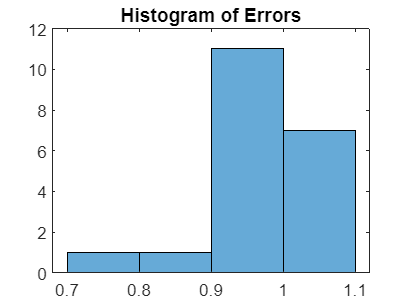


figure;
histogram(errors);
title('Histogram of Errors');

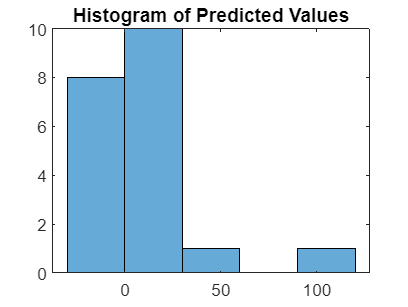


figure;
histogram(predictedValues);
title('Histogram of Predicted Values');

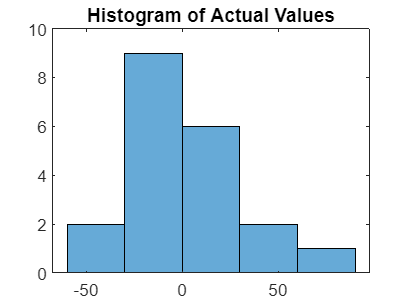


figure;
histogram(actualValues);
title('Histogram of Actual Values');

## Expanding to tensors

addpath('./tensorlab');
addpath('./cvx');

% Parameters
N = 100;  % Number of points in the time series
L = 10;   % Number of rows in each Hankel matrix
num_series = 3;  % Number of sinusoidal signals

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series matrix
time_series_matrix = [signal1];

% Initialize 3D Hankel matrix
H3D = zeros(L, N-L+1, num_series);

% Construct 2D Hankel matrix for each time series and store in 3D Hankel matrix
for i = 1:num_series
    H2D = hankel(time_series_matrix(1:L, i), time_series_matrix(L:N, i));
    H3D(:, :, i) = H2D;
end

Index in position 2 exceeds array bounds. Index must not exceed 1.


% Introduce a missing value (e.g., the last value)
H3D(L, N-L+1, 3) = NaN;  % Example: last value in the third series is missing
H3D
